# Fig. 1905 Stat of Vessel diameter using LME

Load and plot data.

clear;
path(path,'../../_alg');  
path(path,'../../matlab-alg');
path(path,'../../matlab-lib');

tbVDraw = readtable('data1905.xlsx');
tbVDraw.Grp = categorical(tbVDraw.Grp);
tbVDraw.Subj = categorical(tbVDraw.Subj);
tbVDraw.Vessel = categorical(tbVDraw.Vessel);
tbVDraw(:,4:10).Variables = tbVDraw(:,4:10).Variables * 3;  % conf.dx = 3

ivdel = 0;  % delete the vessel when it has 60.0 diameter more than two times
ii=1;
for iv=1:height(tbVDraw)
%     if length(find(tbVDraw(iv,4:10).Variables == 20)) > 1
    if sum(abs(tbVDraw(iv,4:10).Variables-60) < .001) > 1
%         tbVDraw(iv,:) = [];
        ivdel(ii) = iv;  ii = ii+1;
    end
end
tbVDraw(ivdel,:) = [];  % 3 rows were deleted

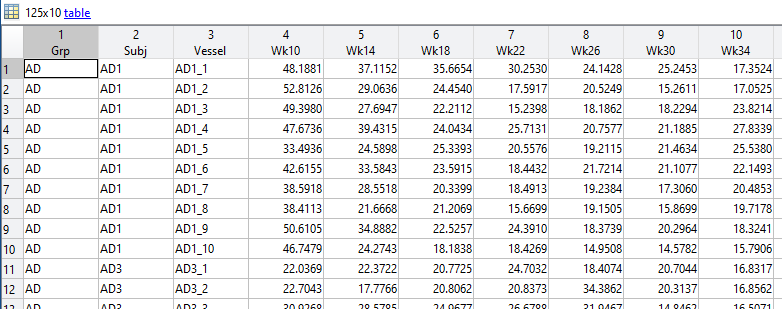

Tukey boxplot

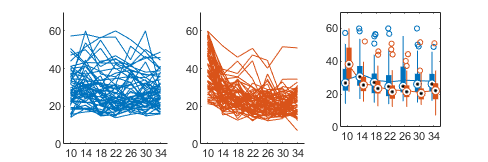

t = (10:4:34);  nt = length(t);
vdWT = tbVDraw(tbVDraw.Grp == "WT",4:10).Variables;
vdAD = tbVDraw(tbVDraw.Grp == "AD",4:10).Variables;

clr = lines(2);
figure('position',[.1 .1 3/4 1/4]*650);
for id=1:2
    if (id == 1),  vd = vdWT;  else,  vd = vdAD;  end;
    subplot(1,3,id);  
        for iv=1:size(vd,1)
            line(t,vd(iv,:),'color',clr(id,:));
        end
        xlim([t(1)-2 t(end)+2]);  ylim([0 70]);
        set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));
%         xlabel('Age (wks)');  
end
subplot(1,3,3);  hold on;
    line(t,mean(vdWT,1),'color',clr(1,:));
    line(t,mean(vdAD,1),'color',clr(2,:));
    boxplot(vdWT,'plotstyle','compact','colors',clr(1,:),'positions',t-0.5);  
    boxplot(vdAD,'plotstyle','compact','colors',clr(2,:),'positions',t+0.5);
    xlim([t(1)-2 t(end)+2]);  ylim([0 70]);
    set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));

%     xlabel('Age (wks)');  

- AD showed a significant trend of decreasing (very early)

# T-test

Plot data.

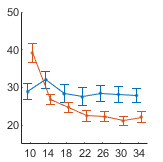

figure('position',[.1 .1 1/4 1/4]*650);  hold on;
for id=1:2
    if (id == 1),  vd = vdWT;  else,  vd = vdAD;  end;
    errorbar(t-0.5+(id-1),mean(vd,1),tinv(0.95,size(vd,1)-1)*std(vd,0,1)/sqrt(size(vd,1)),'color',clr(id,:),'marker','.');
    xlim([t(1)-2 t(end)+2]);  ylim([15 50]);
    set(gca,'xtick',t);  set(gca,'xticklabel',compose('%d',t));
%     xlabel('Age (wks)');  ylabel('Diameter (px)');  title('Vessel diameter with 95% CI');
end

- almost no overlap when plotting 95% CI

## Paired t-test vs t1 (wk 10)

h = zeros(2,nt);
for id=1:2
    if (id == 1),  vd = vdWT;  else,  vd = vdAD;  end;
    for it=1:nt
        h(id,it) = ttest(vd(:,1),vd(:,it));
    end
end
h

h =    NaN     1     0     0     0     0     0
   NaN     1     1     1     1     1     1


- WT showed a significant diameter increase at wk 14

- AD showed all significant decreases at wks 14-34.

T-test analysis was vulnerable to large noise at a specific time point (e.g., WT's t = 14 wk).

## T-test of AD vs. WT

h2 = zeros(1,nt);
for it=1:nt
    h2(it) = ttest2(vdAD(:,it),vdWT(:,it));
end
h2

h2 =      1     1     1     1     1     1     1


- AD and WT were different in vessel diameter for all time

# LME

Prepare table.

tbVD = stack(tbVDraw,4:10,"IndexVariableName","WeekStr","NewDataVariableName","Diameter");
no = height(tbVD);
tbVD.Week = zeros(no,1);
for io=1:no
    wk = string(tbVD(io,:).WeekStr);
    wk = extractBetween(wk,3,4);
    tbVD(io,:).Week = str2num(wk);
end

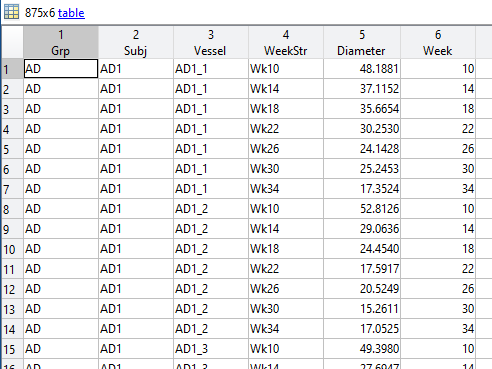

## WT - linear

D_i(t) = b0 + b1 * t + u0_i + eps  where i = Subj

tbVDsub = tbVD(tbVD.Grp == "WT",:);  id = 1;
nos = height(tbVDsub);

lme1 = fitlmematrix([ones(nos,1),tbVDsub.Week], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             406
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3014.9    3030.9    -1503.4          3006.9  

Fixed effects coefficients (95% CIs):
    Name            Estimate     SE        tStat     DF     pValue        Lower      Upper   
    'Offset'           30.822    1.4256     21.62    404    1.9737e-69      28.02      33.625
    'Slope'         -0.094577    0.0609    -1.553    404       0.12121    -0.2143    0.025143

Random effects covariance parameters (95% CIs):
Group: Subj (6 Levels)
    Name1         Name2         Type         Estimate      Lower    Upper
    'u0_i'        'u0_i

lme2 = fitlmematrix([ones(nos,1),tbVDsub.Week], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             406
    Fixed effects coefficients           2
    Random effects coefficients         58
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2657.1    2673.2    -1324.6          2649.1  

Fixed effects coefficients (95% CIs):
    Name            Estimate     SE          tStat      DF     pValue        Lower       Upper    
    'Offset'           30.822      1.3273     23.221    404    2.1644e-76      28.213       33.431
    'Slope'         -0.094577    0.031661    -2.9872    404      0.002987    -0.15682    -0.032337

Random effects covariance parameters (95% CIs):
Group: Vessel (58 Levels)
    Name1         Name2         Type         Estimate    Lower     Upper 
   

[lme1.Rsquared.Ordinary lme2.Rsquared.Ordinary]

ans =     0.0059    0.7495


compare(lme1,lme2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    lme1     4     3014.9    3030.9    -1503.4                               
    lme2     4     2657.1    2673.2    -1324.6    357.71    0          0     


*Unknown ****vessel****-specific offset should be considered, not subject-specific offset.*

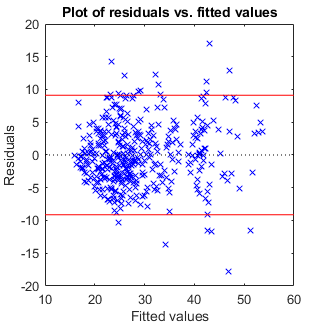

outlierRatio = 0.05;

figure('position',[.1 .1 1/2 1/2]*650);
plotResiduals(lme2,'fitted');
resd = sort(abs(residuals(lme2)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme2)) > thr);
lme3 = fitlmematrix([ones(nos,1),tbVDsub.Week], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             387
    Fixed effects coefficients           2
    Random effects coefficients         58
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    2425    2440.9    -1208.5          2417    

Fixed effects coefficients (95% CIs):
    Name            Estimate    SE          tStat      DF     pValue        Lower       Upper    
    'Offset'          30.968      1.2994     23.833    385    8.7755e-78      28.414       33.523
    'Slope'         -0.11002    0.027621    -3.9832    385    8.1323e-05    -0.16433    -0.055713

Random effects covariance parameters (95% CIs):
Group: Vessel (58 Levels)
    Name1         Name2         Type         Estimate    Lower     Upper 
    'u0_i'

[lme2.Rsquared.Ordinary lme3.Rsquared.Ordinary]

ans =     0.7495    0.8137


compare(lme2,lme3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    lme2     4     2657.1    2673.2    -1324.6                               
    lme3     4       2425    2440.9    -1208.5    232.1     0          0     


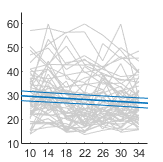

No significant difference from week 10, p(t1,tend)=0.121


ti = (t(1)-2):(t(end)+2);  clrbg = [1 1 1]*0.8;
lme = lme3;
secfig1905a;

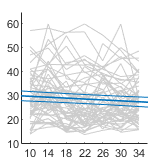

No significant difference from week 10, p(t1,tend)=0.181


lme = lme2;  iol = [];
secfig1905a;

The slope was significant -0.06 ~ -0.16  um/wk (p<0.05).  The offset was 28-34 um

## WT - logistic

f(t;t0,tau) = 1 / ( 1 + exp(-(t-t0)/(tau/5.89)) )  where tau = the period for which 90% of the change occurs.

D_i(t) = b0 + b1 * f(t;t0,tau) + u0_i + eps

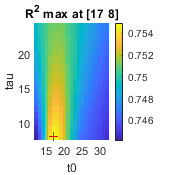

ct0 = (t(1)+2):(t(end)-2);
ctau = 8:24;  % ctau should longer than 8 weeks

r2 = zeros(length(ct0),length(ctau));
for it0=1:length(ct0)
    for itau=1:length(ctau)
        t0 = ct0(it0);
        tau = ctau(itau);
        lme4 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbVDsub.Week-t0)/(tau/5.89)))], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Vessel, ...
            'FixedEffectPredictors', {'Offset','Amplitude'}, ...
            'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'});
        r2(it0,itau) = lme4.Rsquared.Ordinary;
        if r2(it0,itau) == max(r2(:))
            lme5 = lme4;
        end
    end
end
[r2max, idx] = FindMax(r2);  t0 = ct0(idx(1));  tau = ctau(idx(2));
figure('position',[.1 .1 1/4 1/4]*700);  hold on;
imagesc(ct0,ctau,r2');  axis tight;  colorbar;  xlabel('t0');  ylabel('tau');  title(['R^2 max at ' mat2str([t0 tau])]);
line(t0,tau,'marker','+','color','r');

R2 max at the lower boundary (tau=8).  No need to keep going.  Use the linear.

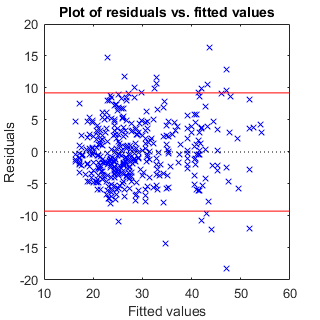

figure('position',[.1 .1 1/2 1/2]*640);
plotResiduals(lme5,'fitted');
resd = sort(abs(residuals(lme5)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme5)) > thr);
lme6 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbVDsub.Week-t0)/(5.89*tau)))], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             387
    Fixed effects coefficients           2
    Random effects coefficients         58
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2429.5    2445.4    -1210.8          2421.5  

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE        tStat      DF     pValue        Lower      Upper 
    'Offset'            39.385     2.9981     13.137    385    7.9353e-33      33.49     45.28
    'Amplitude'        -20.492       5.27    -3.8883    385    0.00011887    -30.853    -10.13

Random effects covariance parameters (95% CIs):
Group: Vessel (58 Levels)
    Name1         Name2         Type         Estimate    Lower     Upper
    'u0_i'  

[lme2.Rsquared.Ordinary lme5.Rsquared.Ordinary]

ans =     0.7495    0.7550


[lme3.Rsquared.Ordinary lme6.Rsquared.Ordinary]

ans =     0.8137    0.8029


compare(lme3,lme6)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    lme3     4       2425    2440.9    -1208.5                               
    lme6     4     2429.5    2445.4    -1210.8    -4.485    0          0     


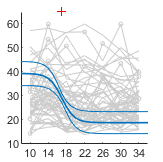

Became significantly different from week 10 at week 17


lme = lme6;
secfig1905b;

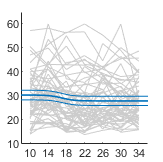

No significant difference from week 10


lme = lme5;  iol = [];
secfig1905b;

lmeWT = lme3;

***R2 decreased from 0.8137 (linear) to 0.8031 (logistic).  Thus, use the linear.***

## AD - linear

D_i(t) = b0 + b1 * t + u0_i + eps  where i = Subj

tbVDsub = tbVD(tbVD.Grp == "AD",:);  id = 2;
nos = height(tbVDsub);

lme1 = fitlmematrix([ones(nos,1),tbVDsub.Week], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             469
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Subj)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3344.7    3361.3    -1668.4          3336.7  

Fixed effects coefficients (95% CIs):
    Name            Estimate    SE          tStat     DF     pValue         Lower       Upper   
    'Offset'          38.263      1.1465    33.374    467    9.7957e-126       36.01      40.516
    'Slope'         -0.57892    0.048977    -11.82    467     2.1907e-28    -0.67517    -0.48268

Random effects covariance parameters (95% CIs):
Group: Subj (7 Levels)
    Name1         Name2         Type         Estimate    Lower    Upper
    'u0_i'      

lme2 = fitlmematrix([ones(nos,1),tbVDsub.Week], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'})

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             469
    Fixed effects coefficients           2
    Random effects coefficients         67
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC       BIC     LogLikelihood    Deviance
    3310.4    3327    -1651.2          3302.4  

Fixed effects coefficients (95% CIs):
    Name            Estimate    SE          tStat     DF     pValue         Lower       Upper   
    'Offset'          38.263      1.1263    33.974    467    2.6687e-128       36.05      40.477
    'Slope'         -0.57892    0.044023    -13.15    467     7.9712e-34    -0.66543    -0.49242

Random effects covariance parameters (95% CIs):
Group: Vessel (67 Levels)
    Name1         Name2         Type         Estimate    Lower     Upper
    'u0_i'    

[lme1.Rsquared.Ordinary lme2.Rsquared.Ordinary]

ans =     0.2295    0.3622


compare(lme1,lme2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    lme1     4     3344.7    3361.3    -1668.4                               
    lme2     4     3310.4      3327    -1651.2    34.375    0          0     


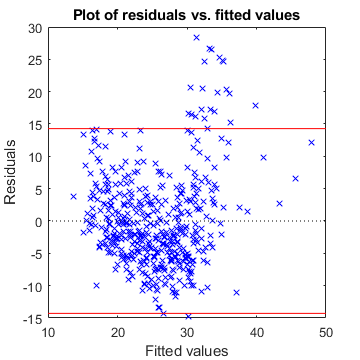

figure('position',[.1 .1 1/2 1/2]*720);
plotResiduals(lme2,'fitted');
resd = sort(abs(residuals(lme2)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme2)) > thr);
lme3 = fitlmematrix([ones(nos,1),tbVDsub.Week], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Slope'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             447
    Fixed effects coefficients           2
    Random effects coefficients         67
    Covariance parameters                2

Formula:
    y ~ Offset + Slope + (u0_i | Vessel)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2930.9    2947.4    -1461.5          2922.9  

Fixed effects coefficients (95% CIs):
    Name            Estimate    SE          tStat      DF     pValue         Lower       Upper   
    'Offset'          33.093     0.95892     34.511    445    6.9139e-128      31.208      34.978
    'Slope'         -0.39362    0.035269    -11.161    445     1.1399e-25    -0.46294    -0.32431

Random effects covariance parameters (95% CIs):
Group: Vessel (67 Levels)
    Name1         Name2         Type         Estimate    Lower     Upper 
    'u

[lme2.Rsquared.Ordinary lme3.Rsquared.Ordinary]

ans =     0.3622    0.4033


compare(lme2,lme3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    lme2     4     3310.4      3327    -1651.2                               
    lme3     4     2930.9    2947.4    -1461.5    379.41    0          0     


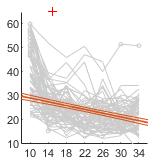

Became significantly different from week 10 at week 15


lme = lme3;

ti = (t(1)-2):(t(end)+2);  clrbg = [1 1 1]*0.8;
secfig1905a;

## AD - logistic

f(t;t0,tau) = 1 / ( 1 + exp(-(t-t0)/(5.89*tau)) )  where tau = the period for which 90% of the change occurs.

D_i(t) = b0 + b1 * f(t;t0,tau) + u0_i + eps

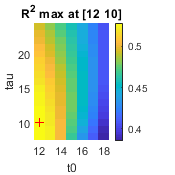

ct0 = (t(1)+2):(t(end)-2);
ctau = 4:24;  % ctau should longer than 4 weeks

ct0 = t(1)+(2:8);
ctau = 8:24;

r2 = zeros(length(ct0),length(ctau));
for it0=1:length(ct0)
    for itau=1:length(ctau)
        t0 = ct0(it0);
        tau = ctau(itau);
        lme4 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbVDsub.Week-t0)/(tau/5.89)))], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Vessel, ...
            'FixedEffectPredictors', {'Offset','Amplitude'}, ...
            'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'});
        r2(it0,itau) = lme4.Rsquared.Ordinary;
        if r2(it0,itau) == max(r2(:))
            lme5 = lme4;
        end
    end
end
[r2max, idx] = FindMax(r2);  t0 = ct0(idx(1));  tau = ctau(idx(2));
figure('position',[.1 .1 1/4 1/4]*700);  hold on;
imagesc(ct0,ctau,r2');  axis tight;  colorbar;  xlabel('t0');  ylabel('tau');  title(['R^2 max at ' mat2str([t0 tau])]);
line(t0,tau,'marker','+','color','r');

- Max at the boundary (t0=12), but we should not decrease t0 less than 10+2 weeks?

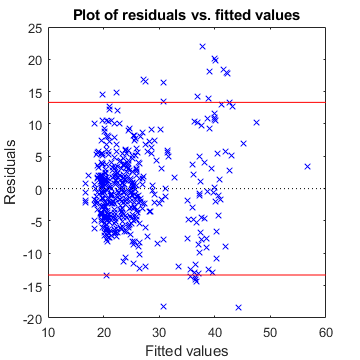

figure('position',[.1 .1 1/2 1/2]*720);
plotResiduals(lme5,'fitted');
resd = sort(abs(residuals(lme5)),'descend');
thr = resd(round(nos*outlierRatio));  
line(get(gca,'xlim'),thr*[1 1],'color','r');
line(get(gca,'xlim'),-thr*[1 1],'color','r');

iol = find(abs(residuals(lme5)) > thr);
lme6 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbVDsub.Week-t0)/(5.89*tau)))], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Vessel, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Vessel'}, ...
    'Exclude',iol)

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             447
    Fixed effects coefficients           2
    Random effects coefficients         67
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3009.4    3025.8    -1500.7          3001.4  

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE        tStat      DF     pValue        Lower      Upper  
    'Offset'            87.297     4.9486     17.641    445    3.4106e-53     77.572     97.023
    'Amplitude'        -115.07     9.0413    -12.728    445    7.3097e-32    -132.84    -97.305

Random effects covariance parameters (95% CIs):
Group: Vessel (67 Levels)
    Name1         Name2         Type         Estimate    Lower     Upper 
    'u0_

[lme2.Rsquared.Ordinary lme5.Rsquared.Ordinary]

ans =     0.3622    0.5286


[lme3.Rsquared.Ordinary lme6.Rsquared.Ordinary]

ans =     0.4033    0.4368


compare(lme5,lme6)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    lme5     4       3201    3217.6    -1596.5                               
    lme6     4     3009.4    3025.8    -1500.7    191.61    0          0     


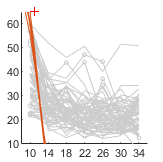

Became significantly different from week 10 at week 11


lme = lme6;
secfig1905b;

- ***R2 and the plot became worse by excluding outliers (R2=0.53 => 0.44)***

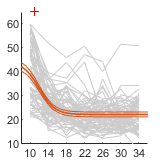

Became significantly different from week 10 at week 11


lme = lme5;  iol = [];
secfig1905b;

R2 increased from 0.40 (linear excluding outliers) to 0.53 (logistic *not *excluding outliers).

lmeAD = lme5

lmeAD = Linear mixed-effects model fit by ML

Model information:
    Number of observations             469
    Fixed effects coefficients           2
    Random effects coefficients         67
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Vessel)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    3201    3217.6    -1596.5          3193    

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE        tStat      DF     pValue         Lower      Upper 
    'Offset'            44.154     1.1463     38.518    467    4.5244e-147     41.901    46.407
    'Amplitude'        -21.846     1.1632    -18.781    467       4.91e-59    -24.131    -19.56

Random effects covariance parameters (95% CIs):
Group: Vessel (67 Levels)
    Name1         Name2         Type         Estimate    Lower     Upper 
    'u0_i' 

***The vessel diameter offset was 42-46 um (95% CI), and decreased by 20-24 um in total, with 90% change across weeks 7-17 (t0=12, tau=10).*** 

save("fig1905 stat vessel diameter.mat")

what if group by Subj?

lme7 = fitlmematrix([ones(nos,1),1./(1+exp(-(tbVDsub.Week-t0)/(tau/5.89)))], tbVDsub.Diameter, [ones(nos,1)], tbVDsub.Subj, ...
    'FixedEffectPredictors', {'Offset','Amplitude'}, ...
    'RandomEffectPredictors', {{'u0_i'}},'RandomEffectGroups',{'Subj'})

lme7 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             469
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2

Formula:
    y ~ Offset + Amplitude + (u0_i | Subj)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3260.2    3276.8    -1626.1          3252.2  

Fixed effects coefficients (95% CIs):
    Name               Estimate    SE        tStat      DF     pValue         Lower      Upper  
    'Offset'            44.154     1.2094     36.508    467    6.6046e-139     41.777     46.531
    'Amplitude'        -21.846     1.3548    -16.124    467     8.0784e-47    -24.508    -19.183

Random effects covariance parameters (95% CIs):
Group: Subj (7 Levels)
    Name1         Name2         Type         Estimate    Lower    Upper
    'u0_i'  

lme7.Rsquared

ans = struct with fields:
    Ordinary: 0.3566
    Adjusted: 0.3553


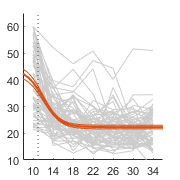

Became significantly different from week 10 at week 11


lme = lme7;
secfig1905b;

## Compare AD vs WT

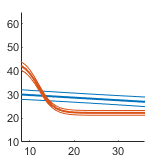

nvWT = size(vdWT,1);
est = lmeWT.Coefficients.Estimate;
se = lmeWT.Coefficients.SE;
covr = lmeWT.CoefficientCovariance;
vdfitmeanWT = est(1) + est(2) .* ti;
vdfitseWT = sqrt( se(1)^2 + ( se(2) .* ti ).^2 + 2*covr(1,2).*ti );

nvAD = size(vdAD,1);
t0 = 12;  tau = 10;
est = lmeAD.Coefficients.Estimate;
se = lmeAD.Coefficients.SE;
covr = lmeAD.CoefficientCovariance;
vdfitmeanAD = est(1) + est(2) ./ (1+exp(-(ti-t0)/(tau/5.89)));
vdfitseAD = sqrt( se(1)^2 + ( se(2) ./ (1+exp(-(ti-t0)/(tau/5.89))) ).^2 + 2*covr(1,2)./(1+exp(-(ti-t0)/(tau/5.89))) );

figure('position',[.1 .1 1/4 1/4]*640);
line(ti,vdfitmeanWT, 'color',clr(1,:), 'linewidth',1.5);
line(ti,vdfitmeanWT+tinv(0.95,nvWT)*vdfitseWT, 'color',clr(1,:));
line(ti,vdfitmeanWT-tinv(0.95,nvWT)*vdfitseWT, 'color',clr(1,:));
line(ti,vdfitmeanAD, 'color',clr(2,:), 'linewidth',1.5);
line(ti,vdfitmeanAD+tinv(0.95,nvAD-1)*vdfitseAD, 'color',clr(2,:));
line(ti,vdfitmeanAD-tinv(0.95,nvAD-1)*vdfitseAD, 'color',clr(2,:));
xlim([t(1)-2 t(end)+2]);  ylim([10 65]);

p = zeros(size(ti));
for it=1:length(p)
    p(it) = GetP_studentT([vdfitmeanWT(it) (vdfitseWT(it)*sqrt(nvWT)) nvWT], [vdfitmeanAD(it) (vdfitseAD(it)*sqrt(nvAD)) nvAD]);
end
p<0.05

ans = 1×29 logical array
   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


- Not good to present

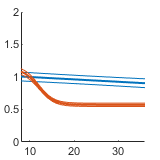

it0 = find(ti==10);
vdfitmeanWTn = vdfitmeanWT / vdfitmeanWT(it0);
vdfitseWTn = vdfitseWT / vdfitmeanWT(it0);
vdfitmeanADn = vdfitmeanAD / vdfitmeanAD(it0);
vdfitseADn = vdfitseAD / vdfitmeanAD(it0);

figure('position',[.1 .1 1/4 1/4]*640);
line(ti,vdfitmeanWTn, 'color',clr(1,:), 'linewidth',1.5);
line(ti,vdfitmeanWTn+tinv(0.95,nvWT)*vdfitseWTn, 'color',clr(1,:));
line(ti,vdfitmeanWTn-tinv(0.95,nvWT)*vdfitseWTn, 'color',clr(1,:));
line(ti,vdfitmeanADn, 'color',clr(2,:), 'linewidth',1.5);
line(ti,vdfitmeanADn+tinv(0.95,nvAD-1)*vdfitseADn, 'color',clr(2,:));
line(ti,vdfitmeanADn-tinv(0.95,nvAD-1)*vdfitseADn, 'color',clr(2,:));
xlim([t(1)-2 t(end)+2]);  ylim([0 2]);